## COVID-19 in BC

**Objective: **To fit the two-age group *SI(R)I(UR)R *model of COVID-19 transmission to the reported case data under various constraints.

## Initialization 

clear all; clc;

%% Select region, timeframe, age-cutoff
region = 'BC';
start_date = 'Mar 1, 2020';
end_date = 'Dec 1, 2020';
age_cutoff = 60;

%% Set parameters
D_T = 5.0;
D = [D_T, D_T]; % Mean infectious period for an I in Group i
T_T = 1;
T = [T_T,T_T]; % Ascertainment fraction of I in Group i 
N = pop_two_groups(age_cutoff); % Estimate for population of Group i 
tspan = 1:1:(datenum(end_date)-datenum(start_date)+1); % timespan over which ODE solved

%% Import data and format to yield cumulative reported cases and initial active cases
dataI = readtable('pathway.csv'); % replace with pathway of file storing cumulative reported case data
observedI = data_selection_two_groups(dataI, start_date, end_date);
y1 = init_cond_two_groups(dataI, start_date, D_T, N, T);

## Optimization: fmincon

c = 0.0990

R0 = 0.9900

ans =    10.0000   10.0000
    9.9800    9.9800
    9.9601    9.9601
    9.9402    9.9402
    9.9203    9.9203
    9.9005    9.9005
    9.8807    9.8807
    9.8609    9.8609
    9.8412    9.8412
    9.8215    9.8215


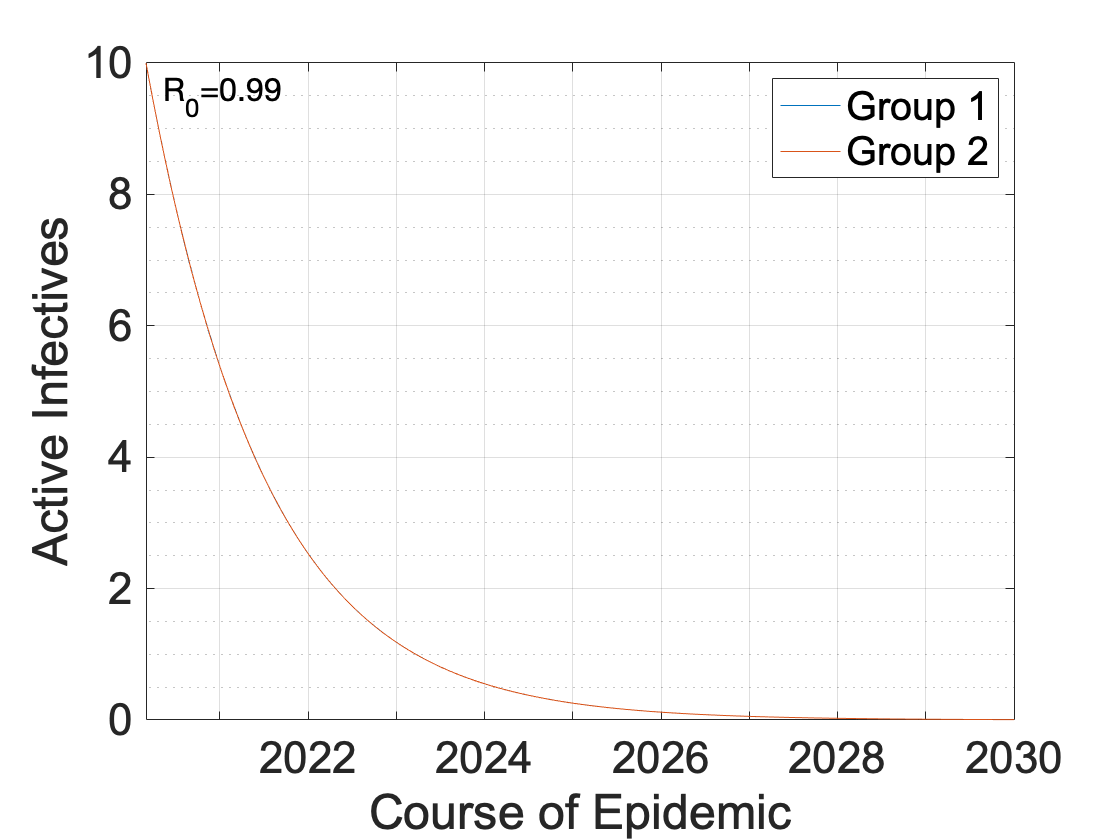

Error using error
Not enough input arguments.

%% Set transmission parameter constraint (must do so in pred_cases_two_groups.m file)
para0 = [0.5, 0.5, 0.1, 0.1];


%% Calculate theoretical epidemic and residual sum of squares
predicted = @(para) pred_cases_two_groups(T, D, N, para, tspan, y1);
min_fun = @(para) sum_squares_two_groups(predicted(para), observedI, tspan);
% min_fun = @(para) sum_squares_two_groups_norm(predicted(para), observedI, tspan);

%% Optimize parameter given constraint
A = [];
b = [];
Aeq = [];
beq = [];
lb = [0,0,0,0];
ub = [1,1,1,1];


para_opt = fmincon(min_fun, para0,A,b,Aeq,beq,lb,ub)
min_fun(para_opt)

% no mixing, varying contact rates between groups
% beta_opt = [para_opt(1), 0; 0, para_opt(2)];

% homogenous mixing, varying contact rates between groups
% beta_opt = [para_opt(1)*(N(1)/sum(N)), para_opt(1)*(N(2)/sum(N)); para_opt(2)*(N(1)/sum(N)), para_opt(2)*(N(2)/sum(N))]

% heterogenous mixing, varying contact rates between groups
% beta_opt = [para_opt(1) * ( N(1) / (N(1)+para_opt(3)*N(2)) ), para_opt(1) * ( para_opt(3)*N(2) / (N(1)+para_opt(3)*N(2)) ); para_opt(2) * ( para_opt(3)*N(1) / (para_opt(3)*N(1)+N(2)) ), para_opt(2) * ( N(2) / (para_opt(3)*N(1)+N(2)) )]

% heterogenous mixing, varying contact rates between groups, varying pref
beta_opt = [para_opt(1) * ( N(1) / (N(1)+para_opt(3)*N(2)) ), para_opt(1) * ( para_opt(3)*N(2) / (N(1)+para_opt(3)*N(2)) ); para_opt(2) * ( para_opt(4)*N(1) / (para_opt(4)*N(1)+N(2)) ), para_opt(2) * ( N(2) / (para_opt(4)*N(1)+N(2)) )];

## Plotting

% Plot predicted cases against observed cases 

obsI = observedI;
pred = predicted(para_opt);

for i = tspan
    graphI (i,1) = pred(i,1);
    graphI (i,2) = pred(i,2);
    graphI (i,4) = obsI(i,1);
    graphI (i,5) = obsI(i,2);
end

date_vector = transpose(datetime(start_date):datetime(end_date));

plot(date_vector,graphI,'LineWidth', 1.5, 'MarkerSize', 18)
legend('Pred(1)','Pred(2)','Obs(1)', 'Obs(2)', 'Location', 'Best')
xlabel(strcat(start_date,'-', end_date))
ylabel('Cumulative Cases')
% title(strcat(region, ': 0-', string(age_cutoff), ',', string(age_cutoff), '+'))
xtickformat('MMM-yy')
grid on;
grid minor;
set(gca, 'FontSize', 22)
set(gca, 'FontName', 'Arial')
text(tspan(length(tspan)), graphI (tspan(length(tspan)),4), '1', "FontSize",20)
text(tspan(length(tspan)), graphI (tspan(length(tspan)),5), '2', "FontSize",20)